### Lavet af: Noah Rahbek Bigum Hansen

### Dato: 13. november 2024

### Studienummer: 202405538

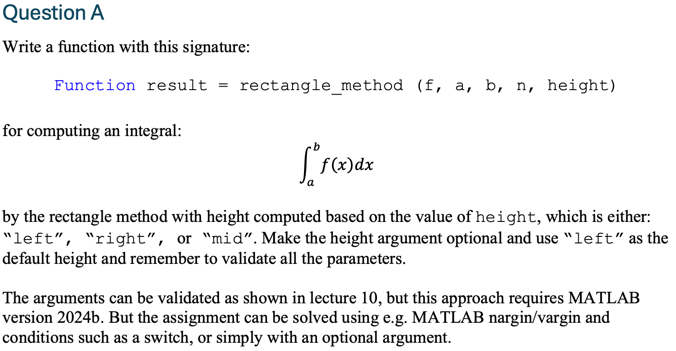

A function with the signature "function result = rectangle_method (f,a,b,n,height)" has been defined in the "Functions"-section at the bottom of this file. To test this function we will first test how it fares against a simple integral. It has been chosen to use the integral of x^2 from 0 to 1 as a test case as this is known to have the accurate value of 1/3. 

%define input variables
f = @(x) x.^2;
a = 0;
b = 1;
n = 100;

%compute the result using different values of the height-variable
resultLeft = rectangle_method(f, a, b, n); %designed to default to "left"
resultRight = rectangle_method(f, a, b, n, "right");
resultMid = rectangle_method(f, a, b, n, "mid");

analyticalResult = 1/3; %define variable containing the analytical result

%print results
fprintf("Left: %.4f, \nRight: %.4f, \nMid: %.4f, \nAnalytical: %.4f", ...
    resultLeft, resultRight, resultMid, analyticalResult);

Left: 0.3284, 
Right: 0.3384, 
Mid: 0.3333, 
Analytical: 0.3333

The code seems to be behaving as expected although the above function will not be tested any more here as the next question revolves around testing the function.

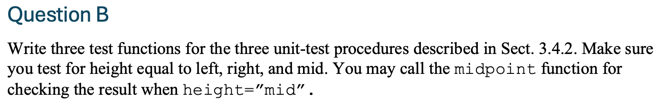

%run the test with a hand computed result for all values of "height" using
%n = 2 to make hand-calculations easier
test_hand_computed_results(f, a, b, "left") 

'Hand-computed result' test passed for height = 'left'.

test_hand_computed_results(f, a, b, "mid") 

'Hand-computed result' test passed for height = 'mid'.

test_hand_computed_results(f, a, b, "right")

'Hand-computed result' test passed for height = 'right'.


%run the test with no numerical error for all values of "height" using a constant
%function as these are known to give 0 error with the rectangle method
test_no_numerical_errors(a, b, 100, "left")

'No numerical error' test passed for height = 'left'.

test_no_numerical_errors(a, b, 100, "mid")

'No numerical error' test passed for height = 'mid'.

test_no_numerical_errors(a, b, 100, "right")

'No numerical error' test passed for height = 'right'.


%run the convergence rate test
test_convergence_rate(f, a, b, 18)

        n          r_left     r_mid    r_right
    __________    ________    _____    _______

             4     -0.8625     -2      -1.1069
             8    -0.93587     -2      -1.0566
            16    -0.96897     -2      -1.0291
            32    -0.98473     -2      -1.0148
            64    -0.99243     -2      -1.0075
           128    -0.99623     -2      -1.0037
           256    -0.99812     -2      -1.0019
           512    -0.99906     -2      -1.0009
          1024    -0.99953     -2      -1.0005
          2048    -0.99977     -2      -1.0002
          4096    -0.99988     -2      -1.0001
          8192    -0.99994     -2      -1.0001
         16384    -0.99997     -2           -1
         32768    -0.99999     -2           -1
         65536    -0.99999     -2           -1
    1.3107e+05          -1     -2           -1
    2.6214e+05   

We have now verified that the function works as expected using the three proper test procedures from the book. We see that we get the same result using the function as calculating the result by hand for a small value of n, we get no numerical error running the test on a constant function as expected and the convergence rates all seem to approach a fixed number for increasing values of n as expected. It seems like "left" and "right" has a convergence rate of -1 and "mid" has a convergence rate of -2 although this has strictly not been shown rigorously. 

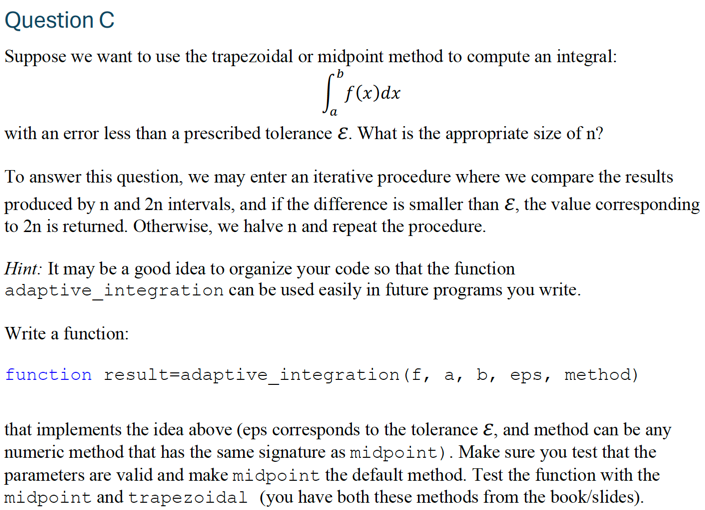

In the following a function called adaptive_integration(f, a, b, eps, method) will be defined. It will support the three different variants of the rectangle method (including the midpoint method) and the trapeziodal method, although only the midpoint- and trapezoidal methods will be tested here as that's all the question calls for.

%note: The function handle has been modified to be able
%to also get it to output the amount of rectangles used
[result_midpoint, n_midpoint] = adaptive_integration(f, a, b, 0.001, "midpoint"); 

%print the result of the integration
fprintf("Using the midpoint method with %d rectangles, \n the result of the integration is %.6f.", ...
    n_midpoint, result_midpoint);

Using the midpoint method with 8 rectangles, 
 the result of the integration is 0.333008.




[result_trapezoidal, n_trapezoidal] = adaptive_integration(f, a, b, 0.001, "trapezoidal");

%print the result of the integration
fprintf("Using the trapezoidal method with %d rectangles, \n the result of the integration is %.6f.", ...
    n_trapezoidal, result_trapezoidal);

Using the trapezoidal method with 16 rectangles, 
 the result of the integration is 0.333496.

From the above we see that the midpoint method needed fewer rectangles than the trapezoidal method to approximate the integral. 

In the following we will test the above adaptive_integration_function on two different functions, with two given tolerances and for two methods (namely the midpoint- and the trapezoidal-methods).

%define the two functions that are to be integrated
f_1 = @(x) x.^2;
f_2 = @(x) sqrt(x);

%define the interval that we are going to integrate over (0 to 2)
a = 0;
b = 2;

%define the exact results for both integrals using the built in integral-function in matlab
exact_f1 = integral(f_1, a, b);
exact_f2 = integral(f_2, a, b);

tolerances = [1e-1, 1e-10]; %define the tolerances

methods = {"midpoint", "trapezoidal"}; %define the methods we are going to be using

for method = methods %loop over all methods
    for eps = tolerances %loop over all given tolerances
        %compute the numerical result for f_1
        result_f1 = adaptive_integration(f_1, a, b, eps, method{1});
        absolute_error_f1 = abs(result_f1 - exact_f1);

        %compute the numerical result for f_2
        result_f2 = adaptive_integration(f_2, a, b, eps, method{1});
        absolute_error_f2 = abs(result_f2 - exact_f2);

        %print the results in a nicely formatted way
        fprintf("========================================"); %add a section break between different methods and tolerances
        fprintf("Method: %s, Tolerance: %.1e", method{1}, eps); %add a header containing the method used and the tolerance with the tolerance formatted in scientific notation
        fprintf("----------------------------------------"); %add smaller section break to distinguish between header and body
        fprintf("Integral of x^2 from 0 to 2:"); %presentation of first integral
        fprintf("  Numerical Result: %.6f", result_f1); %print numerical result
        fprintf("  Exact Result:     %.6f", exact_f1); %print exact result
        fprintf("  Absolute Error:      %.6e", absolute_error_f1); %print absolute error

        fprintf("Integral of sqrt(x) from 0 to 2:"); %presentation of second integral
        fprintf("  Numerical Result: %.6f", result_f2);
        fprintf("  Exact Result:     %.6f", exact_f2);
        fprintf("  Absolute Error:      %.6e", absolute_error_f2);
    end
end

Method: midpoint, Tolerance: 1.0e-01

----------------------------------------

Integral of x^2 from 0 to 2:

  Numerical Result: 2.656250

  Exact Result:     2.666667

  Absolute Error:      1.041667e-02

Integral of sqrt(x) from 0 to 2:

  Numerical Result: 1.931852

  Exact Result:     1.885618

  Absolute Error:      4.623357e-02

Method: midpoint, Tolerance: 1.0e-10

----------------------------------------

Integral of x^2 from 0 to 2:

  Numerical Result: 2.666667

  Exact Result:     2.666667

  Absolute Error:      9.701129e-12

Integral of sqrt(x) from 0 to 2:

  Numerical Result: 1.885618

  Exact Result:     1.885618

  Absolute Error:      2.004574e-11

Method: trapezoidal, Tolerance: 1.0e-01

----------------------------------------

Integral of x^2 from 0 to 2:

  Numerical Result: 2.687500

  Exact Result:     2.666667

  Absolute Error:      2.083333e-02

Integral of sqrt(x) from 0 to 2:

  Numerical Result: 1.861473

  Exact Result:     1.885618

  Absolute Error:      2.414471e-02

Method: trapezoidal, Tolerance: 1.0e-10

----------------------------------------

Integral of x^2 from 0 to 2:

  Numerical Result: 2.666667

  Exact Result:     2.666667

  Absolute Error:      1.940270e-11

Integral of sqrt(x) from 0 to 2:

  Numerical Result: 1.885618

  Exact Result:     1.885618

  Absolute Error:      2.419931e-11

From the above we see that the code behaves as expected giving a reasonably small absolute error for the largest tolerance and a much smaller absolute error for the small tolerance. 

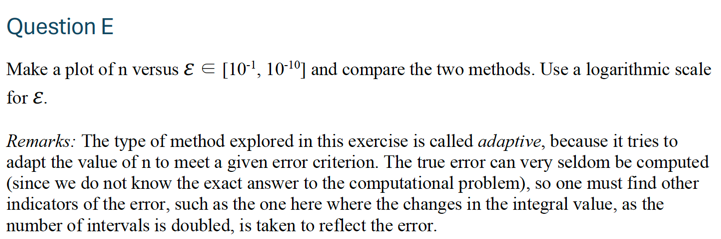

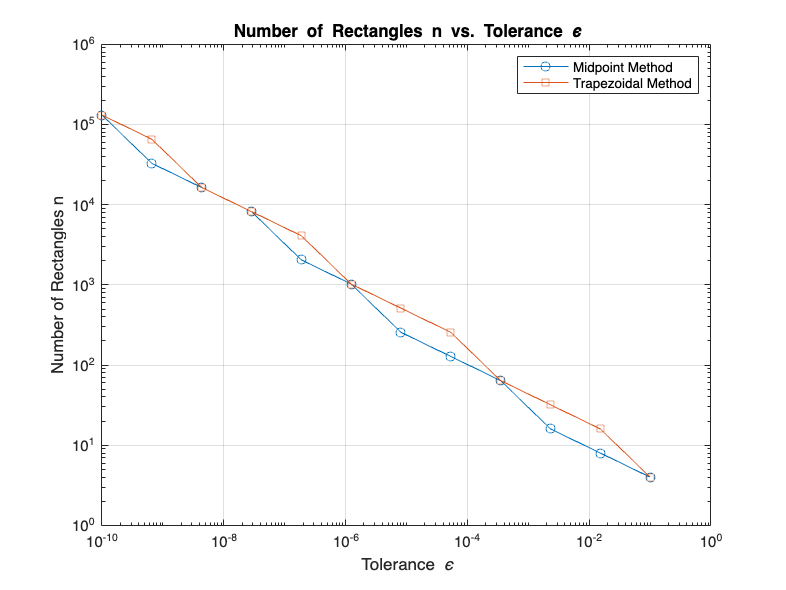

f = @(x) x.^2; %define function to integrate

tolerances = logspace(-10, -1, 12);  %define the tolerance-interval to contain 12 logarithmically spaced points from 10^-10 to 10^-1

%initialize arrays to store amount of rectangles used by each method for all tolerances
n_midpoint = zeros(size(tolerances));
n_trapezoidal = zeros(size(tolerances));

%loop over each tolerance and compute n for both methods
for i = 1:length(tolerances)
    eps = tolerances(i);
    
    %call the midpoint method function but ignore the result of the integration as we are only interested in the amount of rectangles for each tolerance
    [~, n_midpoint(i)] = adaptive_integration(f, a, b, eps, "midpoint");
    
    %call the trapezoidal method function
    [~, n_trapezoidal(i)] = adaptive_integration(f, a, b, eps, "trapezoidal");
end

%plot n versus epsilon for both methods on a double logartihmic scale
figure;
loglog(tolerances, n_midpoint, '-o', 'DisplayName', 'Midpoint Method');
hold on;
loglog(tolerances, n_trapezoidal, '-s', 'DisplayName', 'Trapezoidal Method');
hold off;

%customization of the plot
xlabel('Tolerance \epsilon');
ylabel('Number of Rectangles n');
title('Number of Rectangles n vs. Tolerance \epsilon');
legend();

set(gca, 'MinorGridLineStyle', 'none');  %turn off minor grid lines
grid on;

From the above plot it becomes clear that the midpoint method requires the same amount or fewer rectangles than the trapezoidal method for all error tolerances between 1e-10 and 1e-1

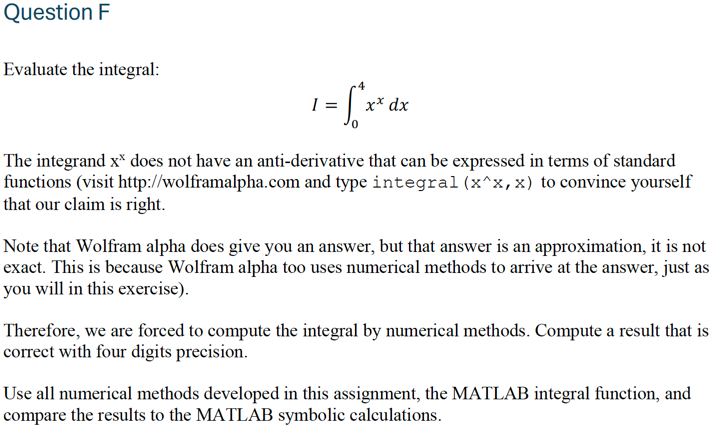

f = @(x) x.^x; %define the function that is to be integrated

%define the interval to integrate over from the assignment
a = 0;
b = 4;

%the result has been found to be approximately equal to 114,1 so 4 digits of
%precision means we need to get it accurate to the first decimal -- which means
%we need to have the error "happen" on the 2nd decimal. If we wanted to get a
%better approximation this value could be made smaller.
tolerance = 1e-2;

%compute the integral using the adaptive midpoint method
[result_midpoint, n_midpoint] = adaptive_integration(f, a, b, tolerance, "midpoint");
fprintf("Adaptive Midpoint Method: \nResult = %.4f, \nRectangles = %d", result_midpoint, n_midpoint);

Adaptive Midpoint Method: 
Result = 114.1175, 
Rectangles = 256


%compute the integral using the adaptive trapezoidal method
[result_trapezoidal, n_trapezoidal] = adaptive_integration(f, a, b, tolerance, "trapezoidal");
fprintf("Adaptive Trapezoidal Method: \nResult = %.4f, \nRectangles = %d", result_trapezoidal, n_trapezoidal);

Adaptive Trapezoidal Method: 
Result = 114.1222, 
Rectangles = 256


%compute the integral using the adaptive rectangle method evaluated at the leftmost points
[result_rec_left, n_rec_left] = adaptive_integration(f, a, b, tolerance, "rec_left");
fprintf("Adaptive Rectangle Method (Left): \nResult = %.4f, \nRectangles = %d", result_rec_left, n_rec_left);

Adaptive Rectangle Method (Left): 
Result = 114.1113, 
Rectangles = 32768


%compute the integral using the adaptive rectangle method evaluated at the rightmost points
[result_rec_right, n_rec_right] = adaptive_integration(f, a, b, tolerance, "rec_right");
fprintf("Adaptive Rectangle Method (Right): \nResult = %.8f, \nRectangles = %d", result_rec_right, n_rec_right);

Adaptive Rectangle Method (Right): 
Result = 114.12684437, 
Rectangles = 32768


%compute the integral using MATLAB's built-in integral function
result_builtin = integral(f, a, b, "AbsTol", tolerance);
fprintf("MATLAB Built-in numerical integral: \nResult = %.4f", result_builtin);

MATLAB Built-in numerical integral: 
Result = 114.1191


%compute the integral using the built-in symbolic capabilities of matlab
%(note: the integral cannot be evaluated symbolically so matlab defaults to
%use a numeric method even though we specifically asked for the symbolic one.
syms x;
f_sym = x^x;
result_symbolic = double(int(f_sym, x, a, b)); %we have to tell matlab to format the result
%as a double for correctly inserting the result in the table
fprintf("'Symbolic' Computation: \nResult = %.4f", result_symbolic);

'Symbolic' Computation: 
Result = 114.1191


%create a table to display the results
MethodNames = [
    "Midpoint Method";
    "Trapezoidal Method";
    "Rectangle Method (Left)";
    "Rectangle Method (Right)";
    "Built-in numerical integral";
    "Symbolic Computation"
];

Results = [
    result_midpoint;
    result_trapezoidal;
    result_rec_left;
    result_rec_right;
    result_builtin;
    result_symbolic
];

RectanglesUsed = [
    n_midpoint;
    n_trapezoidal;
    n_rec_left;
    n_rec_right;
    NaN;  %not applicable for built-in numerical integration function
    NaN   %not applicable for symbolic computation
];

%construct table
ResultsTable = table(MethodNames, Results, RectanglesUsed, ...
    'VariableNames', {'Method', 'Result', 'RectanglesUsed'});

%display table
disp(ResultsTable);

               Method                Result    RectanglesUsed
    _____________________________    ______    ______________

    "Midpoint Method"                114.12          256     
    "Trapezoidal Method"             114.12          256     
    "Rectangle Method (Left)"        114.11        32768     
    "Rectangle Method (Right)"       114.13        32768     
    "Built-in numerical integral"    114.12          NaN     
    "Symbolic Computation"           114.12          NaN     



# Function

function result = rectangle_method(f,a,b,n,height) %define function
    %the function calculates the numeric integral of f from a to b using the rectangle method
    %with n rectangles whose height is determined at the value of the "height"-variable
    arguments %validate input parameters
        f function_handle %check if f is a function
        a double {mustBeNumeric} %check if a is a double (default variable type for scalars in matlab)
        b double {mustBeNumeric} %check if b is a double
        n double {mustBeNumeric} %check if n is a double
        height string {mustBeMember(height, ["left", "mid", "right"])} = "left" %check if the given
        %value of height is either "left", "mid" or "right" and default to "left" if the provided value is not valid
    end

    dx = (b - a)/n; %calculate the width of each rectangle

    switch height %setup system to switch between different methods of applyiung the rectangle method
        case "left" %handles the case where height = "left"
            interval = 0:n-1; %defines interval containing the leftmost points of each rectangle
            x = a + interval * dx; %calculates the heights at the leftmost endpoints of the rectangles
        
        case "mid" %handles the case where height = "mid"
            interval = 0:n-1; %defines interval containing the leftmost points of each rectangle
            x = a + (0.5 + interval) * dx; %calculates the heights at the middle point of the rectangles

        case "right" %handles the case where height = "right"
            interval = 1:n; %defines interval containing the rightmost points of each rectangle
            x = a + interval * dx; %calculates the heights at the rightmost endpoints of each rectangle
    end

    result = sum(f(x) * dx); %computes the result of integration using the previosuly found x-values and
    %summing up the function-values at each x-value and multiplying by the width of each rectangle
end




function test_hand_computed_results(f, a, b, height) %define test-function
    n = 2; %fix n to 2 as this is the n-value used in the hand-computations
    dx = (b - a) / n; %define step-lentgh

    switch height
        case "left"
            hand_computed = f(0 + a) * dx + f(0 + a + dx) * dx; %hand-computed result for height = "left"
            result = rectangle_method(f, a, b, n, "left"); %computation using the previously defined function on height = "left"
        case "mid"
            hand_computed = f(0.5 * dx + a) * dx + f(1.5 * dx + a) * dx; %hand-computed for height = "mid"
            result = rectangle_method(f, a, b, n, "mid"); %height = "mid"
        case "right"
            hand_computed = f(dx + a) * dx + f(2 * dx + a) * dx; %hand-computed for height = "right"
            result = rectangle_method(f, a, b, n, "right"); %height = "right"
    end

    %check if the results are closer than 1e-6 (small error)
    assert(abs(result - hand_computed) < 1e-6, ...
        "'Hand-computed result' test failed for height = '%s'.", height); %print error message if results differ
    fprintf("'Hand-computed result' test passed for height = '%s'.", height); %print "test passed" message if test passes
end




function test_no_numerical_errors(a, b, n, height) %define test-function
%define constant function as these are known to get zero numerical error using the rectangle method irrespective of which value of height is used
    f = @(x) 7 * x.^0; 

    exact_result = integral(f,a,b); %define a variable containing the exact result of the integration using matlabs built-in integral-function

    switch height
        case "left"
            result = rectangle_method(f, a, b, n, "left"); %computation using the previously defined function on height = "left"
        case "mid"
            result = rectangle_method(f, a, b, n, "mid"); %computation using height = "mid"
        case "right"
            result = rectangle_method(f, a, b, n, "right"); %computation using height = "right"
    end
        
    assert(abs(result - exact_result) < 1e-12, ... %check if the numerical error is within the approximate precision of a double variable-type
        "'No numerical error' test failed for height = '%s'.", height);
    fprintf("'No numerical error' test passed for height = '%s'.", height);
end




function test_convergence_rate(f, a, b, num_experiments) %define test-function
    analytical_result = integral(f, a, b); %define the analytical result using matlabs built-in integral-function

    n_values = 2.^(1:num_experiments);  %define the n-values as powers of 2 to be able to test convergence
    
    %initialize arrays to contain error-values for different height-values
    errors_left = zeros(1, num_experiments);
    errors_mid = zeros(1, num_experiments);
    errors_right = zeros(1, num_experiments);

    %calculate the errors for each value of n using the rectangle method function defined previously
    for i = 1:num_experiments
        n = n_values(i);
        errors_left(i) = abs(rectangle_method(f, a, b, n, "left") - analytical_result);
        errors_mid(i) = abs(rectangle_method(f, a, b, n, "mid") - analytical_result);
        errors_right(i) = abs(rectangle_method(f, a, b, n, "right") - analytical_result);
    end

    %calculate the convergence rates using the definition from the book
    r_values_left = log(errors_left(2:end) ./ errors_left(1:end-1)) ./ log(n_values(2:end) ./ n_values(1:end-1));
    r_values_mid = log(errors_mid(2:end) ./ errors_mid(1:end-1)) ./ log(n_values(2:end) ./ n_values(1:end-1));
    r_values_right = log(errors_right(2:end) ./ errors_right(1:end-1)) ./ log(n_values(2:end) ./ n_values(1:end-1));
    
    %prepare values for use in table
    n_values_table = n_values(2:end)'; %we will not get a result of the r_values for n(1) so we will skip this value in the table
    r_values_table = table(n_values_table, r_values_left', r_values_mid', r_values_right', ...
        'VariableNames', {'n', 'r_left', 'r_mid', 'r_right'}); %declaring header-names for the variables in the table

    %display table
    disp(r_values_table);
end




function [result, n_used] = adaptive_integration(f, a, b, eps, method) %define adaptive_integration functuin
    arguments %validate input parameters
        f function_handle
        a double {mustBeNumeric}
        b double {mustBeNumeric}
        eps double {mustBeNumeric} 
        method string {mustBeMember(method, ["midpoint", "trapezoidal", "rec_left", "rec_right"])} = "midpoint" %check if method
        %is supported (either midpoint-method, trapezoidal-method, rectangle-method evaluated at leftmost point or rectangle-
        %method evaluated at rightmost point)
    end

    n = 1; %define initial number of rectangles to 1

    %compute integration results with n and 2n rectangles
    I_n = integrate(f, a, b, n, method);
    I_2n = integrate(f, a, b, 2 * n, method);

    while abs(I_2n - I_n) > eps     %refine n iteratively until the difference is less than eps
        n = 2 * n;  %double amount of intervals if difference is more than eps
        I_n = I_2n;  %update I_n to the previous I_2n
        I_2n = integrate(f, a, b, 2 * n, method);  %run computation with 2n intervals
    end

    result = I_2n; %return the result of the adaptive numerical integration
    n_used = n;  %return the number of rectangles used
end




function result_integration = integrate(f, a, b, n, method) %define helper function to apply the correct method to the adaptive_integration-function

    dx = (b - a) / n; %define step-length
    
    switch method %set up system to switch between the different methods
        case "midpoint" %call the midpoint function from the book if method = "midpoint"
            x = linspace(a + dx/2, b - dx/2, n);
            result_integration = dx*sum(f(x));
        case "trapezoidal" %call the trapezoidal function from the book if method = "trapezoidal"
            x = linspace(a, b, n+1);
            result_integration = dx*(sum(f(x)) - 0.5*f(a) - 0.5*f(b));
        case "rec_left" %call the previously defined rectangle method with height = "left" if method = "rec_left"
            result_integration = rectangle_method(f, a, b, n, "left");
        case "rec_right" %call the previously defined rectangle method with height = "right" if method = "rec_right"
            result_integration = rectangle_method(f, a, b, n, "right");
    end
end 